# **Matlab案例代码解析**

## 7. 神经网络和机器学习案例

### 7.3 LSTM

#### 7.3.2 LSTM预测

#### 资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期 → P值下浮率

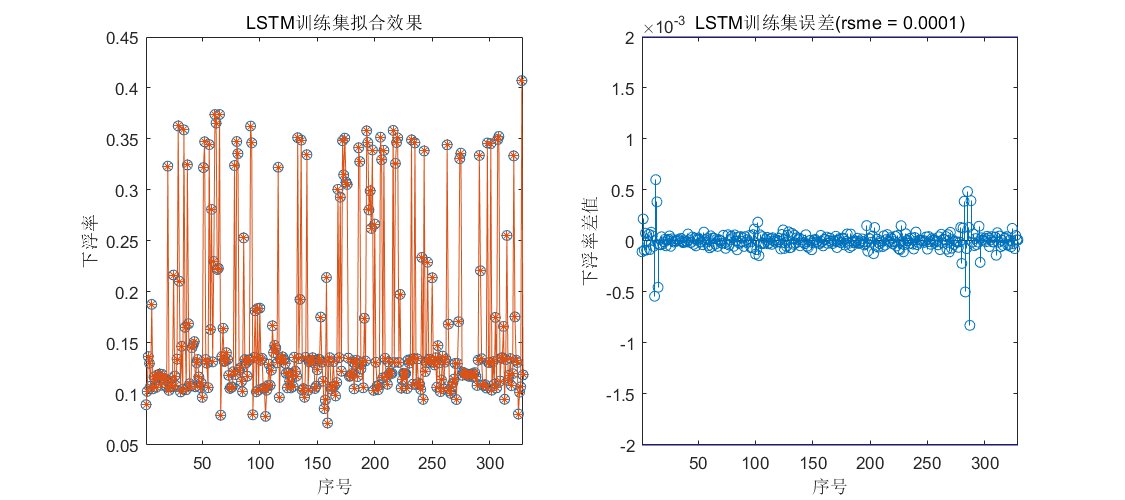

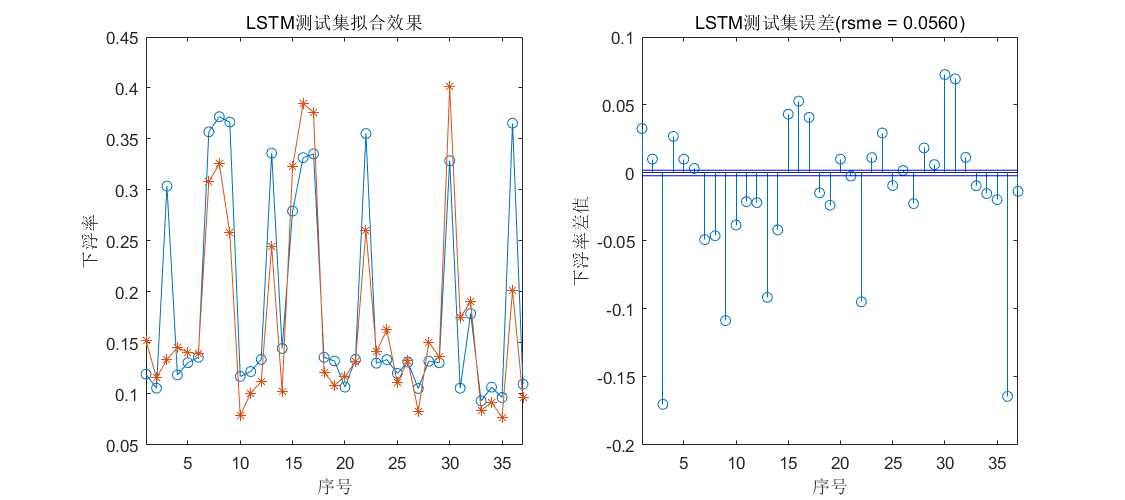

#### 选择下浮率小于 0.15 部分：资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期 → P值下浮率

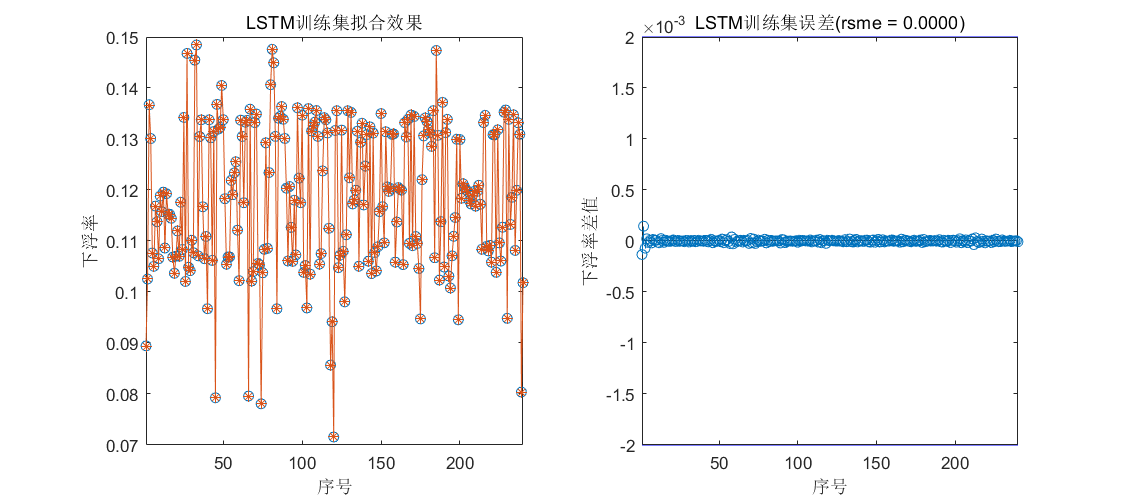

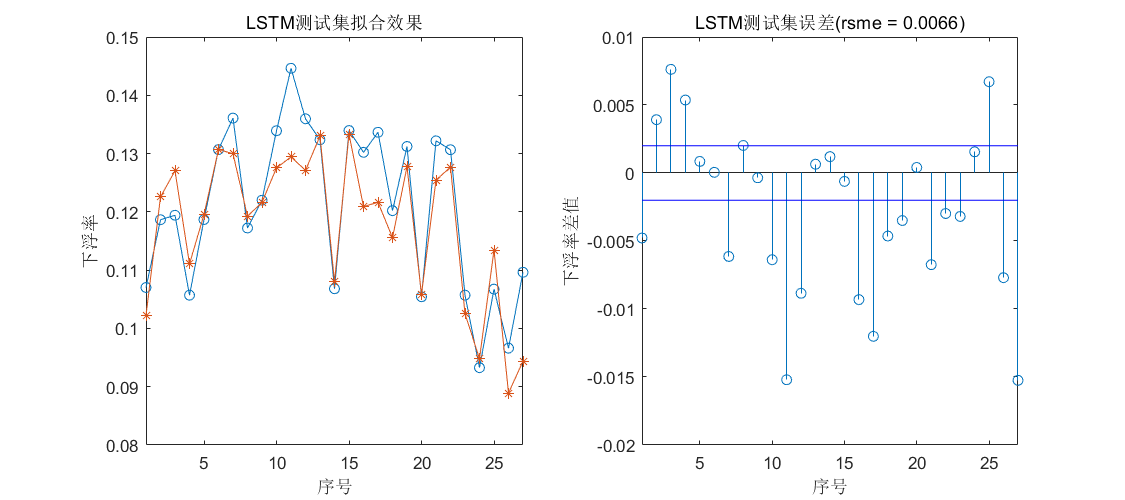

**调参，不同参数结果显著差异；**

**为防止过拟合，需要加大学习数据集；**

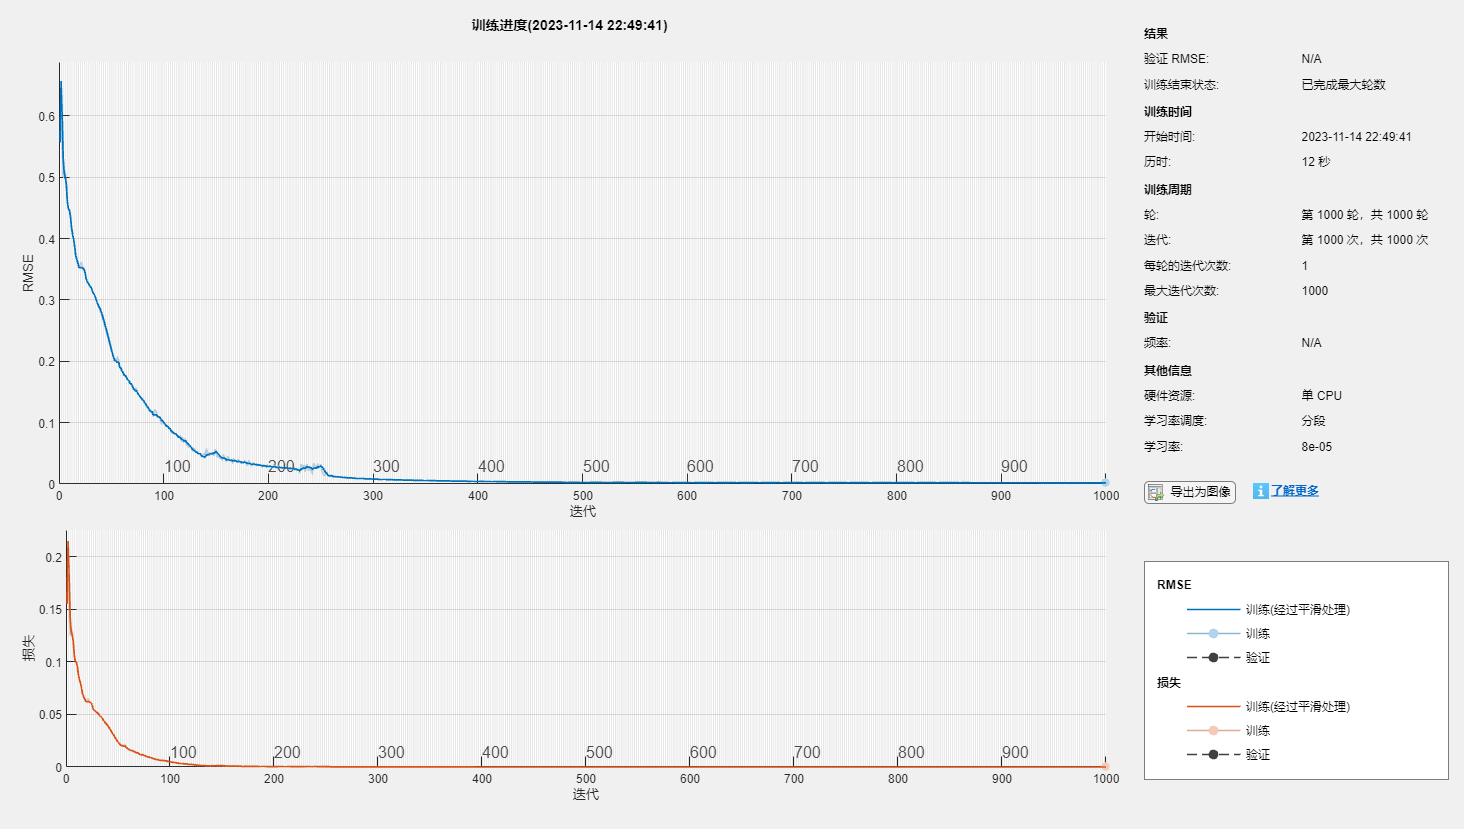

clear;clc;close all;
%%%%%%%%%%%%%%%%%%%%%%%%%% 加载数据
filename = 'data\zb.xlsx';
file = readtable(filename, 'Sheet', 1, 'VariableNamingRule', 'preserve');
data = table2array(file(:, 2:end));
% 数据筛选
% indx = find(data(:, end) <= 0.15);
% data = data(indx, :);
% 输入、输出数据提取
% 方式一：已知信息 → 未知信息
output = data(:, end);
input = data(:, 1:end-2);
% 方式二：已知信息 + 之前的结果信息 → 未知信息
% output = data(2 : end, end);
% input = [data(2 : end, 1 : end-2), data(1 : end-1, end)];
% 数据分成训练集和测试集
train_number = floor(0.7 * size(data, 1));
test_number = size(data, 1) - train_number;
xTrain = input(1:train_number, :);
yTrain = output(1:train_number, :);
xTest = input(train_number+1 : end, :);
yTest = output(train_number+1 : end, :);
% 归一化
[XTrain, PSx] = mapminmax(xTrain');
[YTrain, PSy] = mapminmax(yTrain');
XTest = mapminmax('apply', xTest', PSx);
%%%%%%%%%%%%%%%%%%%%%%%%%% 构建 LSTM 网络
% 输入特征的维度
numFeatures = size(input, 2);
% LSTM 网路包含的隐藏单元数目
numHiddenUnits = 30;
% 输出响应维度
numResponses = 1;
% 重点注意 regressionLayer
layers = [sequenceInputLayer(numFeatures)
          lstmLayer(numHiddenUnits)
          fullyConnectedLayer(numResponses)
          regressionLayer];
miniBatchSize = 64;
options = trainingOptions('adam', ...
                          'ExecutionEnvironment', 'cpu', ...
                          'MaxEpochs', 1000, ...
                          'MiniBatchSize', miniBatchSize, ...
                          'GradientThreshold', 1, ...
                          'InitialLearnRate', 0.01, ...
                          'LearnRateSchedule', 'piecewise', ...
                          'LearnRateDropPeriod', 250, ...
                          'LearnRateDropFactor', 0.2, ...
                          'Verbose', false, ...
                          'Plots', 'training-progress');
% 训练
net = trainNetwork(XTrain, YTrain, layers, options);

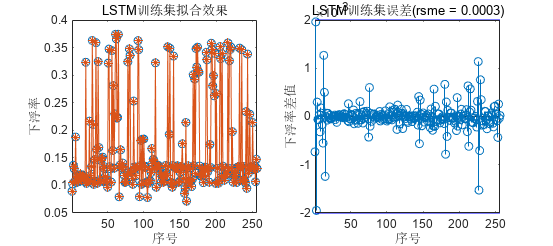

% 训练效果
yTrain_pre = predict(net, XTrain, 'MiniBatchSize', miniBatchSize, 'SequenceLength', 'longest');
% 反归一化
yTrain_pre = mapminmax('reverse', yTrain_pre, PSy);
yTrain_pre = yTrain_pre';
% 差值
err_train = yTrain_pre - yTrain;
% 均方误差
rmse_train = rms(err_train);
line_acc = 0.002 * ones(1, train_number);
% 画图
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1);
plot(yTrain, '-o');
hold on
plot(yTrain_pre, '-*');
hold off
xlabel('序号');
ylabel('下浮率');
title('LSTM训练集拟合效果');
xlim([1, train_number]);
subplot(1, 2, 2);
stem(err_train);
hold on
plot(line_acc, 'b');
plot(-line_acc, 'b');
hold off
xlim([1, train_number]);
xlabel('序号');
ylabel('下浮率差值');
title(sprintf('LSTM训练集误差(rsme = %.4f)', rmse_train));

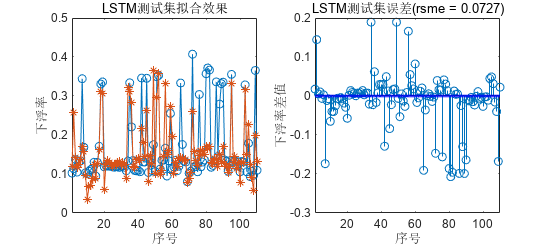

%%%%%%%%%%%%%%%%%%%%%%%%%% 测试效果
yTest_pre = predict(net, XTest, 'MiniBatchSize', miniBatchSize, 'SequenceLength', 'longest');
% 反归一化
yTest_pre = mapminmax('reverse', yTest_pre, PSy);
yTest_pre = yTest_pre';
% 差值
err_test = yTest_pre - yTest;
% 均方误差
rmse_test = rms(err_test);
% 画图
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1);
plot(yTest, '-o');
xlabel('序号');
ylabel('下浮率');
title('LSTM测试集拟合效果');
hold on
plot(yTest_pre, '-*');
hold off
xlim([1, test_number]);
subplot(1, 2, 2);
stem(err_test);
xlabel('序号');
ylabel('下浮率差值');
title(sprintf('LSTM测试集误差(rsme = %.4f)', rmse_test));
hold on
plot(line_acc, 'b');
plot(-line_acc, 'b');
hold off
xlim([1, test_number]);